# **PROJECT ROBOTICS II : Study of a Planar Robot 4 axes **

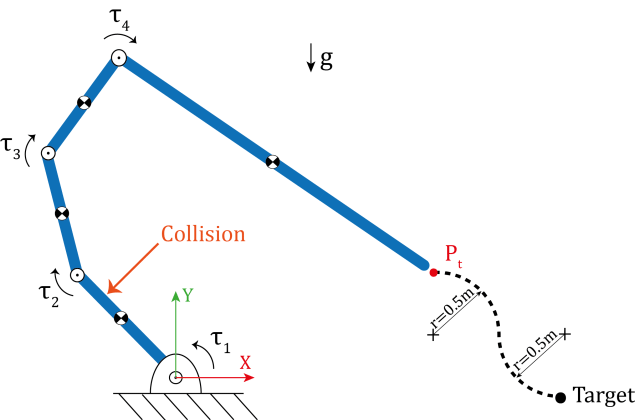

## Main Script  : 

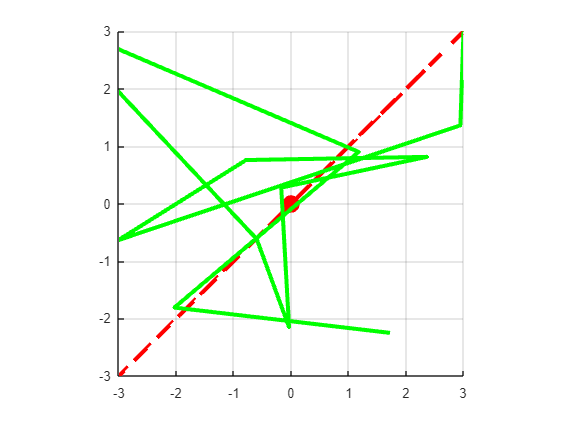

L1_val = 1.5;
L2_val = 1.5;
L3_val = 1.5;
L4_val = 1.5;
n = 100;
a = 0.1;
b = 5;
c = 2.73;
t = linspace(1,10,n);
initial_angle1 = 0;
initial_angle2 = 0;
initialGuess = [initial_angle1, initial_angle2,0,0]; 

% main3() % Pseudo Inverse position
% simulate_robot_trajectory(n, t, L1_val, L2_val, L3_val, L4_val) % Pseudo Inverse
% main() % Pseudo Inverse Speed  ( for training only )
%main4() % Null space ( Version I, work but dont see the robot, good trajectory but bad space )
%simulateRobotKinematics(n, l1, l2, l3, l4, t, a, c) % Null space with the
%robot simulation trajectory
%simulateTaskAugmentation(n, L1, L2, L3, L4)

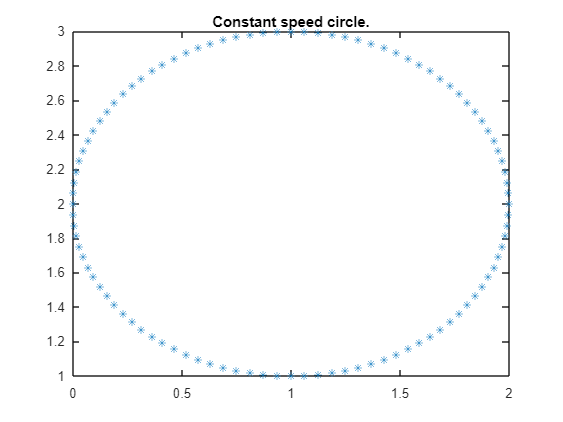



RobotTrajectorynullspace()

xlim([-0.0211 0.0214])
ylim([-0.0428 0.0260])
view([48.0561 -5.5340])
view([83.5181 42.5237])
view([89.6649 23.0474])

xlim([-0.095 0.026])
ylim([-0.0428 0.0332])

function  []=RobotPlotter(q,p,l1,l2,l3,l4,dt) 
figure
n=numel(q(1,:));
w=[];
for i=1:n
    X0=[0 0 0]';
    X1=[l1*cos(q(1,i))
        l1*sin(q(1,i))
        0];
    X2=[l1*cos(q(1,i))+l2*cos(q(1,i)+q(2,i))
        l1*sin(q(1,i))+l2*sin(q(1,i)+q(2,i))
        0];
    X3=[l1*cos(q(1,i))+l2*cos(q(1,i)+q(2,i))+l3*cos(q(1,i)+q(2,i)+q(3,i))
        l1*sin(q(1,i))+l2*sin(q(1,i)+q(2,i))+l3*sin(q(1,i)+q(2,i)+q(3,i))
        0];
    X4=[l1*cos(q(1,i))+l2*cos(q(1,i)+q(2,i))+l3*cos(q(1,i)+q(2,i)+q(3,i))+l4*cos(q(1,i)+q(2,i)+q(3,i)+q(4,i))
        l1*sin(q(1,i))+l2*sin(q(1,i)+q(2,i))+l3*sin(q(1,i)+q(2,i)+q(3,i))+l4*sin(q(1,i)+q(2,i)+q(3,i)+q(4,i))
        0];

    X=[X0 X1 X2 X3 X4];
    w=[w X4];

    hold off
    plot3(X(1,1:5),X(2,1:5),X(3,1:5), '-o','LineWidth',3,'MarkerSize',10,'MarkerEdgeColor','r','MarkerFaceColor','r');
    hold on
    grid on
    
    plot3(p(1,1:i),p(2,1:i),zeros(1,i),'--r','LineWidth',3);
    plot3(w(1,:),w(2,:),w(3,:),'g','LineWidth',3);
        axis([-3 3 -3 3]);
        axis square;
        view(0,90);
        pause(dt);

   %exportgraphics(gcf,'trace_robot.gif','Append',true);
end
end


## Trajectories commands  : 

function points = generate_circular_trajectory(n_points, radius, center)
    if nargin < 3
        center = [0, 0]; 
    end
    
    theta = linspace(0, 2 * pi, n_points);
    x = center(1) + radius * cos(theta);
    y = center(2) + radius * sin(theta);
    points = [x', y'];
end

function points = generate_linear_trajectory(n_points, start_point, end_point)
    vector = end_point - start_point;
    t = linspace(0, 1, n_points);
    x = start_point(1) + vector(1) * t;
    y = start_point(2) + vector(2) * t;
    points = [x; y]';
end


function trajectory = generate_helical_trajectory(num_points, radius, pitch, center)
    if nargin < 4
        center = [0, 0]; 
    end
    if nargin < 3
        pitch = 0.01;
    end
    if nargin < 2
        radius = 0.01;
    end
    cx = center(1);
    cy = center(2);
    t_values = linspace(0, 2 * pi, num_points);
    x_values = radius * cos(t_values) + cx;
    y_values = radius * sin(t_values) + cy;
    trajectory = [x_values; y_values]';
end

## Direct geometrics Model II: 

function [x, y] = MGD_A2(L1_val,L2_val,L3_val,L4_val, q1, q2,q3,q4)
    x = L1_val * cos(q1) + L2_val * cos(q1 + q2) + L3_val * cos(q1 + q2 + q3) + L4_val * cos(q1 + q2 + q3 + q4);
    y = L1_val * sin(q1) + L2_val * sin(q1 + q2) + L3_val * sin(q1 + q2 + q3) + L4_val * sin(q1 + q2 + q3 + q4);
end

## Inverse geometrics Model I : 

function [q1, q2, q3, q4] = InverseKinematics_NR(L1, L2, L3, L4, x_target, y_target, q_initial, maxIter, tolerance)
    q = q_initial;
    for iter = 1:maxIter
        [x, y] = MGD_A2(L1, L2, L3, L4, q(1), q(2), q(3), q(4));
        error = [x - x_target; y - y_target];
        if norm(error) < tolerance
            fprintf('Solution found after %d iterations.\n', iter);
            break;
        end
        J = CalculateJacobian(L1, L2, L3, L4, q);
        % q = q - inv(J) * error
        q = q - pinv(J) * error;
    end
    q1 = q(1);
    q2 = q(2);
    q3 = q(3);
    q4 = q(4);
end

function J = CalculateJacobian(L1, L2, L3, L4, q)
    J = [-L1*sin(q(1)) - L2*sin(q(1) + q(2)) - L3*sin(q(1) + q(2) + q(3)) - L4*sin(q(1) + q(2) + q(3) + q(4)), ...
         -L2*sin(q(1) + q(2)) - L3*sin(q(1) + q(2) + q(3)) - L4*sin(q(1) + q(2) + q(3) + q(4)), ...
         -L3*sin(q(1) + q(2) + q(3)) - L4*sin(q(1) + q(2) + q(3) + q(4)), ...
         -L4*sin(q(1) + q(2) + q(3) + q(4));
         L1*cos(q(1)) + L2*cos(q(1) + q(2)) + L3*cos(q(1) + q(2) + q(3)) + L4*cos(q(1) + q(2) + q(3) + q(4)), ...
         L2*cos(q(1) + q(2)) + L3*cos(q(1) + q(2) + q(3)) + L4*cos(q(1) + q(2) + q(3) + q(4)), ...
         L3*cos(q(1) + q(2) + q(3)) + L4*cos(q(1) + q(2) + q(3) + q(4)), ...
         L4*cos(q(1) + q(2) + q(3) + q(4))];
end

## Inverse kinematic model : Pseudo Inverse

function main1() % Newton Raphson Command and Pseudo Inverse with minimize error, wihtout robot simulation
    L1_val = 0.1;
    L2_val = 0.1;
    L3_val = 0.1;
    L4_val = 0.1;
    initial_angle1 = 0;
    initial_angle2 = 0;
    initial_angle3 = 0;
    initial_angle4 = 0;
    initialGuess = [initial_angle1, initial_angle2, initial_angle3, initial_angle4];
    nombre_points = 1000;
    trajectory_points = generate_circular_trajectory(nombre_points, 0.015, [0.3, 0]);
    A2_positions = zeros(size(trajectory_points));  

    initialGuess_NR = [0, 0, 0, 0]; 
    for i = 1:size(trajectory_points, 1)
        point = trajectory_points(i, :);
        x_target = point(1);
        y_target = point(2);
        tol = 0.001;
        maxIter = 1000; 
        [q1, q2, q3, q4] = InverseKinematics_NR(L1_val, L2_val, L3_val, L4_val, x_target, y_target, initialGuess_NR, maxIter, tol);
        [x_out, y_out] = MGD_A2(L1_val, L2_val, L3_val, L4_val, q1, q2, q3, q4);
        A2_positions(i, :) = [x_out, y_out];
    end

    figure('Name', 'Trajectory Visualization');
    plot(trajectory_points(:, 1), trajectory_points(:, 2), 'cyan', 'LineWidth', 2, 'DisplayName', 'Desired Trajectory');
    hold on;
    scatter(A2_positions(:, 1), A2_positions(:, 2), 'red', 'MarkerEdgeColor', 'red', 'SizeData', 10, 'DisplayName', 'Reachable Trajectory');
    xlabel('X axis');
    ylabel('Y axis');
    grid on;
    legend('show');
    title('Trajectory Comparison');
    hold off;
end

function simulate_robot_trajectory(n, t, L1, L2, L3, L4) % Robot simulation for Null space proyection
    rayon = 1;
    center = [1, 2];
    theta = linspace(0, 2*pi, n);
    x = center(1) + rayon * cos(theta);
    y = center(2) + rayon * sin(theta); % Circle
    r = [x; y];
    time_intervals = diff(t);
    r_d = diff(r, 1, 2) ./ time_intervals;
    rc_d = r_d;  % Assuming rc_dot follows r_dot
    r_p = zeros(2, n-1);
    q_p = zeros(4, n);
    q_p(:, 1) = [0; 0; pi/2; 0]; 
    r_p(:, 1) = MGD_A2(L1, L2, L3, L4, q_p(1, 1), q_p(2, 1), q_p(3, 1), q_p(4, 1));
    for i = 1:n-1
        Jaco = CalculateJacobian(L1, L2, L3, L4, q_p(:, i));
        J_p = pinv(Jaco);
        dq = J_p * r_d(:, i);
        q_p(:, i+1) = q_p(:, i) + (t(i+1) - t(i)) * dq;
        r_p(:, i+1) = MGD_A2(L1, L2, L3, L4, q_p(1, i+1), q_p(2, i+1), q_p(3, i+1), q_p(4, i+1));
    end

    figure;
    subplot(2, 1, 1);
    plot(r_p(1, :), r_p(2, :), '*-','Color', 'green');
    hold on;
    plot(r(1, :), r(2, :), "x",'Color', 'magenta');
    title('Trajectory');
    hold off;

    subplot(2, 1, 2);
    plot(t(1:n-1), sqrt((r_p(1, 1:n-1) - r(1, 1:n-1)).^2 + (r_p(2, 1:n-1) - r(2, 1:n-1)).^2),'Color', 'blue');
    title('Error');

    RobotPlotter(q_p, r_p, L1, L2, L3, L4, 0.001);
end


##  Method I : Pseudo Inverse ( Correction minimizing the error )

function main3()
    L1_val = 0.1;
    L2_val = 0.1;
    L3_val = 0.1;
    L4_val = 0.1;
    nombre_points = 1000;
    delta_t = 0.01;
    trajectory_points = generate_circular_trajectory(nombre_points, 0.015, [0.3, 0]);
    q = zeros(nombre_points, 4); 
    joint_velocities = zeros(nombre_points - 1, 4);
    A2_positions = zeros(nombre_points, 2);
    q_initial = [0, 0, 0, 0];
    tolerance = 0.001;
    maxIter = 1000;
    
    for i = 1:(nombre_points - 1)
        r_dot = (trajectory_points(i + 1, :) - trajectory_points(i, :)) / delta_t;
        
        [q1, q2, q3, q4] = InverseKinematics_NR(L1_val, L2_val, L3_val, L4_val, ...
                                                 trajectory_points(i + 1, 1), trajectory_points(i + 1, 2), ...
                                                 q(i, :), maxIter, tolerance);
        q(i + 1, :) = [q1, q2, q3, q4];
        J = CalculateJacobian(L1_val, L2_val, L3_val, L4_val, q(i + 1, :));
        q_dot = pinv(J) * r_dot';
        joint_velocities(i, :) = q_dot;
        [x_out, y_out] = MGD_A2(L1_val, L2_val, L3_val, L4_val, q1, q2, q3, q4);
        A2_positions(i + 1, :) = [x_out, y_out];
    end
    figure;
    plot(trajectory_points(:, 1), trajectory_points(:, 2), 'cyan', 'LineWidth', 2);
    hold on;
    scatter(A2_positions(:, 1), A2_positions(:, 2), 'MarkerEdgeColor', 'red', 'SizeData', 10);
    xlabel('X axis (meters)');
    ylabel('Y axis (meters)');
    title('Trajectory Following with Velocity Control');
    legend('Desired Trajectory', 'Actual End-Effector Path');
    grid on;
    hold off;
end


##  Method II : Null space Projection commande en vitesse 

function main4()
    L1_val = 0.1;
    L2_val = 0.1;
    L3_val = 0.1;
    L4_val = 0.1;
    nombre_points = 1000;
    trajectory_points = generate_circular_trajectory(nombre_points, 0.015, [0,0]);
    A2_positions = zeros(nombre_points, 2);
    q_current = zeros(4, 1);
    delta_t = 0.01; % Example time interval
    for i = 1:(nombre_points - 1)
        current_point = trajectory_points(i, :);
        next_point = trajectory_points(i + 1, :);
        r_dot = (next_point - current_point) / delta_t;
        J = CalculateJacobian(L1_val, L2_val, L3_val, L4_val, q_current);
        J_pseudo_inverse = pinv(J);
        q_dot_0 = zeros(4, 1);
        secondary_speed = 0.001; 
        null_space_basis = null(J);
        q_dot_0 = zeros(4, 1);
        if ~isempty(null_space_basis)
              q_dot_0 = null_space_basis(:, 1) * secondary_speed;
              q_dot_0 = reshape(q_dot_0, [4, 1]);
        end
        q_dot = J_pseudo_inverse * r_dot' + (eye(4) - J_pseudo_inverse * J) * q_dot_0;
        q_current = q_current + q_dot * delta_t;
        [x_out, y_out] = MGD_A2(L1_val, L2_val, L3_val, L4_val, q_current(1), q_current(2), q_current(3), q_current(4));
        A2_positions(i + 1, :) = [x_out, y_out];
    end
    plot_trajectory_and_positions(trajectory_points, A2_positions);
end

function RobotTrajectorynullspace()
    L1 = 1.5;
    L2 = 1.5;
    L3 = 1.5;
    L4 = 1.5;
    n = 100;
    t = linspace(1,10,n);
    [xc, yc] = calculateCircleTrajectory(n);
    [r, rc] = calculateTrajectories(xc, yc, t, n);
    figure;
    plot(rc(1,:), rc(2,:), '*');
    title("Constant speed circle.");
    [r_dot, rc_dot] = calculateTrajectoryDerivatives(r, rc, t, n);
    [q_null, r_null] = simulateNullSpaceTrajectory(L1, L2, L3, L4, r_dot, t, n);    
    plotTrajectoriesAndErrors(r, r_null, t, n);
    RobotPlotter(q_null, r_null, L1, L2, L3, L4, 0.01);
end

function [xc, yc] = calculateCircleTrajectory(n)
    rayon = 1;
    center = [1,2];
    xc = zeros(1,n);
    yc = zeros(1,n);
    for i=1:n
        xc(i) = center(1) + rayon*cos((i-1)*2*pi/n);
        yc(i) = center(2) + rayon*sin((i-1)*2*pi/n);
    end
end

function [r, rc] = calculateTrajectories(xc, yc, t, n)
    r = [xc' yc']';
    rc = r; % Utilisation de la même trajectoire pour simplifier
end

function [r_dot, rc_dot] = calculateTrajectoryDerivatives(r, rc, t, n)
    r_dot = zeros(2,n-1);
    rc_dot = zeros(2,n-1);
    for i=1:n-1
        r_dot(:,i) = (r(:,i+1)-r(:,i))/(t(i+1)-t(i));
        rc_dot(:,i) = (rc(:,i+1)-rc(:,i))/(t(i+1)-t(i));
    end
end

function [q_null, r_null] = simulateNullSpaceTrajectory(L1, L2, L3, L4, r_dot, t, n)
    q_null = zeros(4,n);
    r_null = zeros(2,n);
    syms q1 q2 q3 q4;
    vec = [q1 q2 q3 q4];
    q0dot = -gradient(cost(q1,q2,q3,q4),vec); % À définir
    q_null(:,1) = [0; 0; pi/2; 0]; % Conditions initiales
    for i=1:n-1
        Jacobian = CalculateJacobian(L1, L2, L3, L4, q_null(:, i)); % À définir
        q0dot_calc = eval(subs(q0dot, vec, q_null(:,i)'));
        dq = q0dot_calc + pinv(Jacobian)*(r_dot(:,i)-Jacobian*q0dot_calc);
        q_null(:,i+1) = q_null(:,i) + (t(i+1)-t(i))*dq;
        r_null(:,i) = MGD_A2(L1, L2, L3, L4, q_null(1, i+1), q_null(2, i+1), q_null(3, i+1), q_null(4, i+1)); % À définir
    end
end


function plotTrajectoriesAndErrors(r, r_null, t, n)
    % Visualisation des trajectoires
    figure;
    plot(r_null(1,1:n-1), r_null(2,1:n-1), 'm-', 'LineWidth', 2); % Trajectoire nulle en magenta
    hold on;
    plot(r(1,:), r(2,:), 'gx'); % Trajectoire réelle en vert avec des croix
    title('Trajectory for Null Space');
    legend('Null Space Trajectory', 'Real Trajectory', 'Location', 'best');
    grid on;
    hold off;
    
    % Visualisation de l'erreur cartésienne
    figure;
    plot(t(1:n-1), sqrt((r_null(1,1:n-1) - r(1,1:n-1)).^2 + (r_null(2,1:n-1) - r(2,1:n-1)).^2), 'k', 'LineWidth', 2);
    title('Cartesian Error for Null Space');
    xlabel('Time (s)');
    ylabel('Error (m)');
    grid on;
end

function plot_trajectory_and_positions(trajectory_points, A2_positions)
    figure;
    plot(trajectory_points(:, 1), trajectory_points(:, 2), 'magenta', 'LineWidth', 2);
    hold on;
    scatter(A2_positions(:, 1), A2_positions(:, 2), 'green', 'filled');
    xlabel('X position (meters)');
    ylabel('Y position (meters)');
    title('Trajectory Following with Velocity Control');
    legend('Desired Trajectory', 'Actual End-Effector Path');
    grid on;
    hold off;
end

function output = cost(q1, q2, q3, q4)
    % Penalize the deviation of q1 from pi/2
    deviation_penalty = (q1 - pi/2)^2;
    
    % Add smaller penalties for movement in other joints to encourage minimal movement
    joint_penalty = q2^2 + q3^2 + q4^2;
    
    % Combine penalties; weight the deviation penalty higher
    output = 10 * deviation_penalty + 0.1 * joint_penalty;
end


###  Method III : Task Augmention Command

function main5()
    L1_val = 0.1;
    L2_val = 0.1;
    L3_val = 0.1;
    L4_val = 0.1;
    nombre_points = 1000;
    delta_t = 0.01; % Example time interval
    trajectory_points = generate_circular_trajectory(nombre_points, 0.015, [0, 0]);
    q_current = zeros(4, 1);
    joint_velocities = zeros(4, nombre_points - 1);
    A2_positions = zeros(nombre_points, 2);
    for i = 1:(nombre_points - 1)
        r_dot_desired = (trajectory_points(i + 1, :) - trajectory_points(i, :))' / delta_t;
        J_current = CalculateJacobian(L1_val, L2_val, L3_val, L4_val, q_current);
        J_pseudo_inverse = pinv(J_current);
        f_y = []; % Auxiliary task
        J_y = []; % Jacobian of the auxiliary task
        J_A = [J_current; J_y];
        r_A = [r_dot_desired; f_y];
        q_dot = K_A(q_current) * r_A;
        I = eye(length(q_current));
        q_dot_null = (I - J_A' * pinv(J_A)) * q_dot_0; % q_dot_0 is arbitrary
        q_dot = q_dot + q_dot_null;
        joint_velocities(:, i) = q_dot;
        q_current = q_current + q_dot * delta_t;
        [x_out, y_out] = MGD_A2(L1_val, L2_val, L3_val, L4_val, q_current);
        A2_positions(i + 1, :) = [x_out, y_out];
    end
    
    plot_trajectory_and_positions(trajectory_points, A2_positions);
end


function simulateTaskAugmentation(n, L1, L2, L3, L4)
    q_taskAug = zeros(4,n);
    r_taskAug = zeros(2,n);
    q_taskAug(:,1) = [0; 0; pi/2; 0];
    
    r_taskAug(:,1) = MGD_A2(L1, L2, L3, L4, q_taskAug(1,1), q_taskAug(2,1), q_taskAug(3,1), q_taskAug(4,1));
    
    Jacobian_augmentedTask = [0 0 0 1];
    syms q1 q2 q3 q4 real;
    grad = cost_augmented(q1,q2,q3,q4); % Assume cost_augmented is defined elsewhere

    t = linspace(1, 10, n);
    [xc, yc] = calculateCircleTrajectory(n);
    [r, rc] = calculateTrajectories(xc, yc, t, n);
    [r_dot, rc_dot] = calculateTrajectoryDerivatives(r, rc, t, n);

    for i = 1:n-1
        dr = [r_dot(:,i); eval(subs(grad, [q1, q2, q3, q4], q_taskAug(:,i)'))];
        J_Augmented = [CalculateJacobian(L1, L2, L3, L4, q_taskAug(:,i)); Jacobian_augmentedTask];
        J_Augmented_inv = pinv(J_Augmented);
        dq = J_Augmented_inv * dr;
        q_taskAug(:,i+1) = q_taskAug(:,i) + (t(i+1) - t(i)) * dq;
        r_taskAug(:,i+1) = MGD_A2(L1, L2, L3, L4, q_taskAug(1,i+1), q_taskAug(2,i+1), q_taskAug(3,i+1), q_taskAug(4,i+1));
    end
    plotTrajectoryAndErrors(r_taskAug, r, t);
    RobotPlotter(q_taskAug, r_taskAug, L1, L2, L3, L4, 0.01);
end

function plotTrajectoryAndErrors(r_taskAug, r, t)
    figure;
    plot(r_taskAug(1,1:end-1), r_taskAug(2,1:end-1), '*-');
    hold on;
    plot(r(1,:), r(2,:), "x");
    title('Trajectory for Task Augmentation')
    hold off;
    
    errors = sqrt((r_taskAug(1,1:end-1) - r(1,1:end-1)).^2 + (r_taskAug(2,1:end-1) - r(2,1:end-1)).^2);
    figure;
    plot(t(1:end-1), errors);
    title('Cartesian error for Task Augmentation')
end

function cost = cost_augmented(q1, q2, q3, q4)
    desired_q4 = -q1 - q2 - q3;  
    weight = 10;  
    cost = weight * (q4 - desired_q4)^2; 
end


##  Method III : Task Priority

function simulateTaskPriority(n, L1, L2, L3, L4, t)
    q_priority = zeros(4, n);
    r_priority = zeros(2, n); 
    q_priority(:,1) = [0; 0; pi/2; 0];
    r_priority(:,1) = MGD_A2(L1, L2, L3, L4, q_priority(:,1));

    J2 = [0 1 0 0];
    J3 = [0 0 1 0];
    for i = 1:n-1
        dr1 = r_dot(:,i);  % r_dot doit être défini ou passé en argument
        dr2 = 0;
        dr3 = 0;
        Jacobian = CalculateJacobian(L1, L2, L3, L4, q_priority(:,i));
        J_pseudo = pinv(Jacobian);
        P1 = eye(4) - J_pseudo * Jacobian;
        P2 = eye(4) - pinv(J2 * P1) * J2 * P1;
        dq = J_pseudo * dr1 + P1 * pinv(J2 * P1) * (dr2 - J2 * J_pseudo * dr1) + P2 * pinv(J3 * P2 * P1) * (dr3 - J3 * P2 * pinv(J3 * P2 * P1) * dr2);
        q_priority(:,i+1) = q_priority(:,i) + (t(i+1) - t(i)) * dq;
        r_priority(:,i+1) = MGD_A2(L1, L2, L3, L4, q_priority(:,i+1));
    end
    disp(size(r_priority));

    figure
    plot(r_priority(1,1:n-1), r_priority(2,1:n-1), 'k*');
    hold on;
    plot(r(1,:), r(2,:), "x");
    title('Trajectory for Task Priority')
    hold off;
    errors = sqrt((r_priority(1,1:n-1) - r(1,1:n-1)).^2 + (r_priority(2,1:n-1) - r(2,1:n-1)).^2);
    figure;
    plot(t(1:n-1), errors);
    title('Cartesian error for Task Priority');
    figure;
    plot(t(1:n-1), q_priority(2,1:n-1));   % Error on second link
    title('Error on second task for Task Priority');
    figure;
    plot(t(1:n-1), abs(pi/2 - q_priority(3,1:n-1))); % Error on third link
    title('Error on third task for Task Priority');
    RobotPlotter(q_priority, r_priority, L1, L2, L3, L4, 0.01);
function simulateRobotControl(n, L1, L2, L3, L4, t)
    [xc, yc] = calculateCircleTrajectory(n);
    [r, ~] = calculateTrajectories(xc, yc, t, n);
    [r_dot, ~] = calculateTrajectoryDerivatives(r, r, t, n);
    q_pseudo = zeros(4, n);
    q_pseudo(:,1) = [-pi/6; -pi/8; pi/2; 0];
    r_pseudo = zeros(2, n);
    r_pseudo(:,1) = MGD_A2(L1, L2, L3, L4, q_pseudo(:,1));
    kp = 10;
    for i = 1:n-1
        dr1 = r_dot(:,i);
        err = r(:,i) - MGD_A2(L1, L2, L3, L4, q_pseudo(:,i));
        Jacobian = CalculateJacobian(L1, L2, L3, L4, q_pseudo(:,i));
        J_pseudo = pinv(Jacobian);
        dq = J_pseudo * (dr1 + kp * err);
        q_pseudo(:,i+1) = q_pseudo(:,i) + (t(i+1) - t(i)) * dq;
        r_pseudo(:,i+1) = MGD_A2(L1, L2, L3, L4, q_pseudo(:,i+1));
    end

    % Plotting trajectories and errors
    figure;
    hold on;
    plot(r_pseudo(1,1:n-1), r_pseudo(2,1:n-1), 'DisplayName', 'Pseudo Inverse Trajectory');
    plot(r(1,1:n-1), r(2,1:n-1), 'DisplayName', 'Desired Trajectory');
    legend show;
    hold off;
    title('Trajectory for Pseudo Inverse with Control');
    % Error plotting
    errors = sqrt((r_pseudo(1,1:n-1) - r(1,1:n-1)).^2 + (r_pseudo(2,1:n-1) - r(2,1:n-1)).^2);
    figure;
    plot(t(1:n-1), errors);
    title('Cartesian Error for Pseudo Inverse with Control');
    % Robot plotting function (needs to be defined or adapted)
    RobotPlotter(q_pseudo, r_pseudo, L1, L2, L3, L4, 0.1);
end


##  Method III : Control Pseudo inverse Kinematics 


function simulateRobotControl(n, L1, L2, L3, L4, t)
    % Calculate the circular trajectory
    [xc, yc] = calculateCircleTrajectory(n);
    [r, ~] = calculateTrajectories(xc, yc, t, n);
    [r_dot, ~] = calculateTrajectoryDerivatives(r, r, t, n);
    % Initialize the pseudo inverse control variables
    q_pseudo = zeros(4, n);
    q_pseudo(:,1) = [-pi/6; -pi/8; pi/2; 0];
    r_pseudo = zeros(2, n);
    r_pseudo(:,1) = MGD_A2(L1, L2, L3, L4, q_pseudo(:,1));
    kp = 10;
    % Main control loop
    for i = 1:n-1
        dr1 = r_dot(:,i);
        err = r(:,i) - MGD_A2(L1, L2, L3, L4, q_pseudo(:,i));
        Jacobian = CalculateJacobian(L1, L2, L3, L4, q_pseudo(:,i));
        J_pseudo = pinv(Jacobian);
        dq = J_pseudo * (dr1 + kp * err);
        q_pseudo(:,i+1) = q_pseudo(:,i) + (t(i+1) - t(i)) * dq;
        r_pseudo(:,i+1) = MGD_A2(L1, L2, L3, L4, q_pseudo(:,i+1));
    end
    % Plotting trajectories and errors
    figure;
    hold on;
    plot(r_pseudo(1,1:n-1), r_pseudo(2,1:n-1), 'DisplayName', 'Pseudo Inverse Trajectory');
    plot(r(1,1:n-1), r(2,1:n-1), 'DisplayName', 'Desired Trajectory');
    legend show;
    hold off;
    title('Trajectory for Pseudo Inverse with Control');
    % Error plotting
    errors = sqrt((r_pseudo(1,1:n-1) - r(1,1:n-1)).^2 + (r_pseudo(2,1:n-1) - r(2,1:n-1)).^2);
    figure;
    plot(t(1:n-1), errors);
    title('Cartesian Error for Pseudo Inverse with Control');
    RobotPlotter(q_pseudo, r_pseudo, L1, L2, L3, L4, 0.1);
end
